# Practice with Matrices

Previously, you imported a matrix from a data file, fixed a false value, converted the units, and visualized the result. In this reading, you'll go through these concepts and some additional ones. You'll also get the chance to practice new skills in the code blocks.

## Creating Matrices

You've learned how to import a matrix from a data file, but you'll often need to create matrices within your scripts. For example, you may have imported multiple sets of data and need to join them together in a single matrix. How do you create your own matrices?

### Concatenation with Values

You've created vectors by grouping elements with square brackets. You used spaces between elements for row vectors and semicolons for column vectors.

To create a matrix, combine these two techniques. Use spaces to separate numbers in a row and semicolons to separate each row.

The variable `myFirstMatrix` has 3 rows and 2 columns. This is called a 3x2 (pronounced *"three by two"*) matrix.

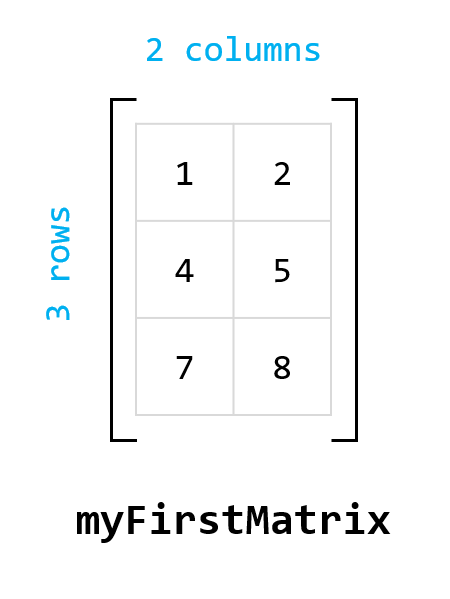

Create your own 2x2 matrix with ones in the first column and zeros in the second column. Store it in a new variable, `newMatrix`.

### Concatenation with Vectors and Matrices

If you want to concatenate existing vectors or matrices, they must* fit together*, like blocks that were designed to be attached to each other. For example, a matrix with 3 rows could be concatenated to a column vector with 3 elements. 

To concatenate horizontally, use a space between the items you are combining. To concatenate vertically, use a semicolon.

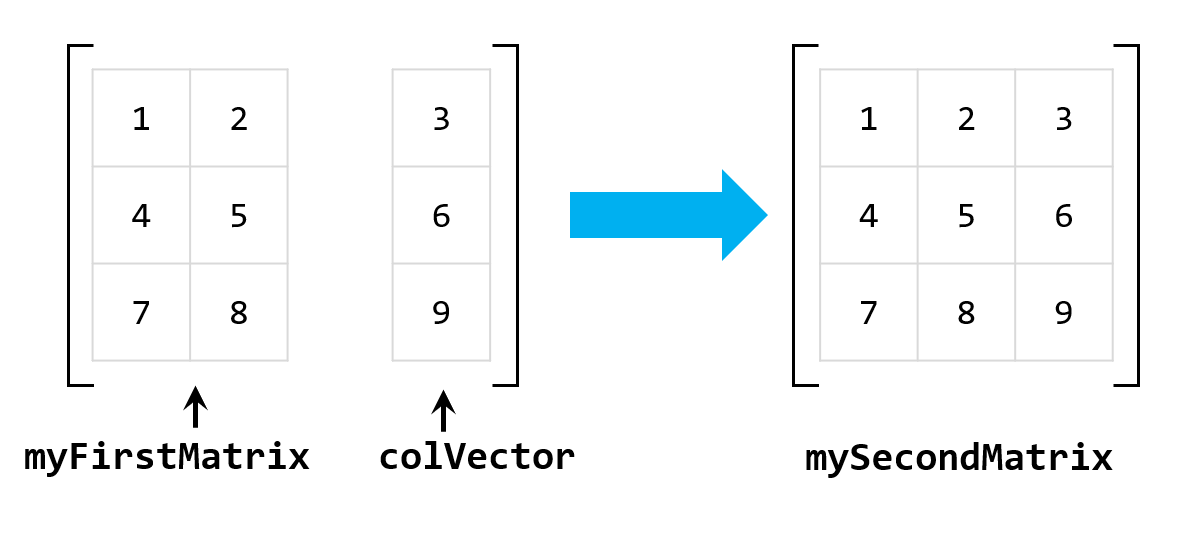

The concatenation will fail if the dimensions are not consistent, like when trying to concatenate a row vector with 3 elements onto a matrix with 2 columns.

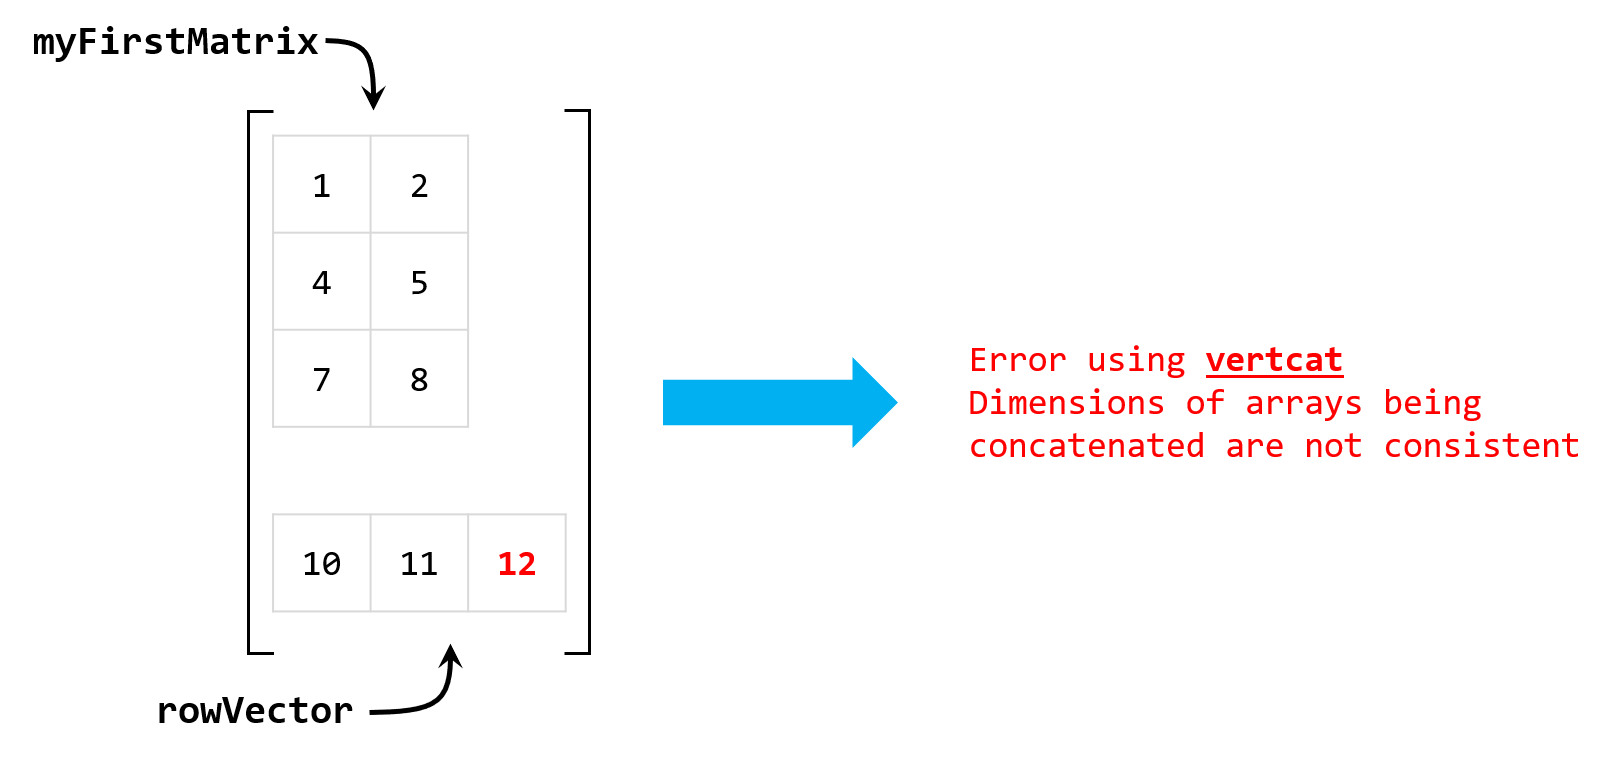

Try this yourself with the matrix `rain1`. It contains the rainfall (in inches) for various adjacent regions. The matrix `extraVals` contains additional rainfall values from an adjacent region.

rain1 = [1 2 3; 2 3 3; 1 2 3; 1 1 2]  
extraVals = [3 4; 4 4; 4 4; 4 5] 

Concatenate the matrix `extraVals` horizontally onto the matrix `rain1`. Store the output in `rain2`.

Use `surf` to visualize `rain2`. Label the z-axis "Inches of Rain" using `zlabel`.

### Matrix-Creation Functions

If you need to create a larger matrix, you don't need to type out every element. Rather, there are several functions that create matrices. These are helpful in many situations, like generating random values to test your code. These functions include:

- [ones](https://www.mathworks.com/help/matlab/ref/ones.html)

- [zeros](https://www.mathworks.com/help/matlab/ref/zeros.html)

- [rand](https://www.mathworks.com/help/matlab/ref/rand.html)

- [randi](https://www.mathworks.com/help/matlab/ref/randi.html)

- [randn](https://www.mathworks.com/help/matlab/ref/randn.html)

- [eye](https://www.mathworks.com/help/matlab/ref/eye.html)

For example, create a matrix of zeros with the `zeros` function. Specify the number of desired rows and columns as inputs.

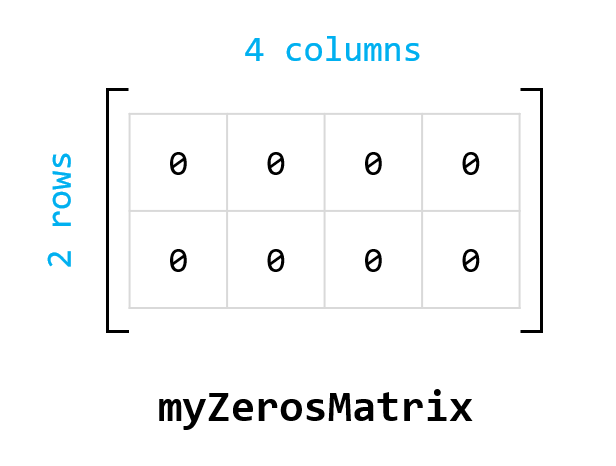

For random values, use functions like `rand`, `randn`, and `randi`.

Notice the number of rows or columns can be 1, meaning these functions can generate vectors as well. In fact, a vector* is* a matrix, where either the row or column size is 1. 

Now try this out yourself. The rainfall values in the previous section varied between 1 and 5 inches. Below, generate some simulated rainfall data with values in the same range. Use `randi` to create a new 4x5 matrix with values in the range `[1 5]`. Store the output in `rain3`.

Insert a "Create Plot" live task below and choose a visualization style to represent `rain3`.

## Accessing and Manipulating Matrices

You can use indices to access and manipulate the data in matrices. This is useful, for example, when data has false values or outliers that need to be replaced. 

### Row-Column Indexing

Matrices have both rows and columns, so both the row and column indices are used to access values.

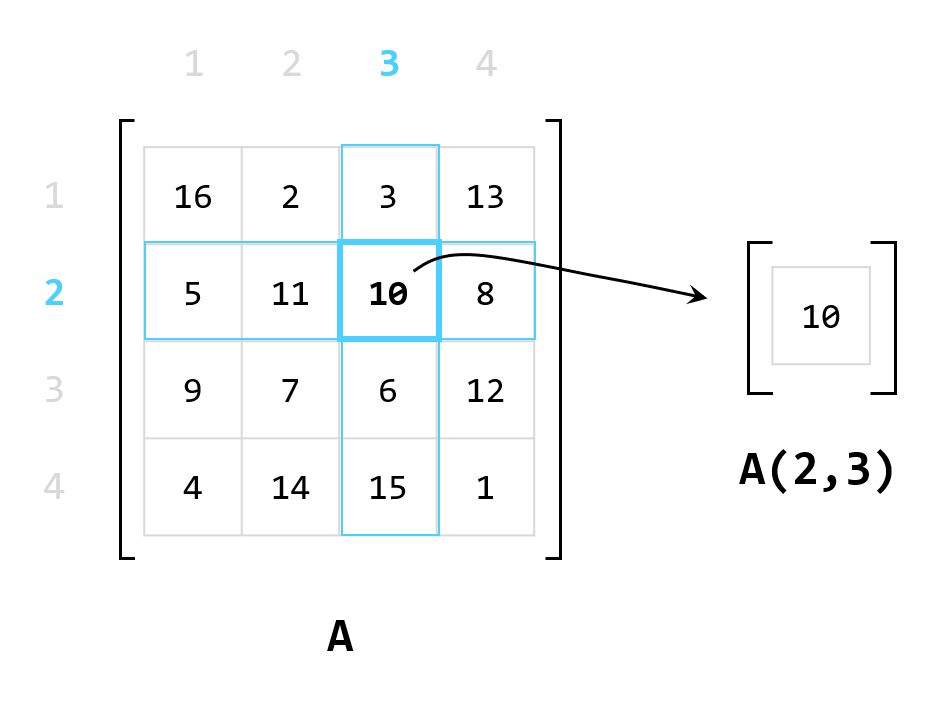

If you need to extract all the values in a row or column, use a single colon as an index.

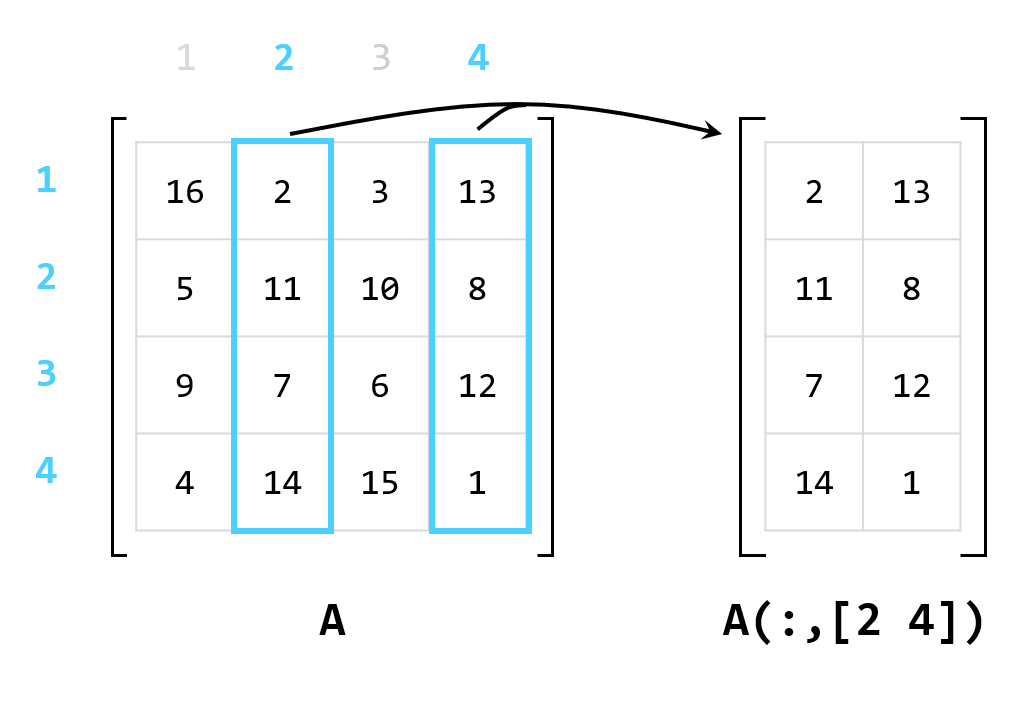

To replace values, use the same indexing syntax and assign the new value. You can replace multiple values with a single value or another matrix/vector of the same size.

Try this yourself. Create a 5x5 matrix of zeros and replace the first row with the integers 1 to 5.

### Logical Indexing

When you need to fix values that are out of a sensor's range, for example, you'll need to find values that meet a certain condition. As with vectors, you can specify a condition to create a logical variable. The logical variable contains the location of the elements that satisfy that condition. 

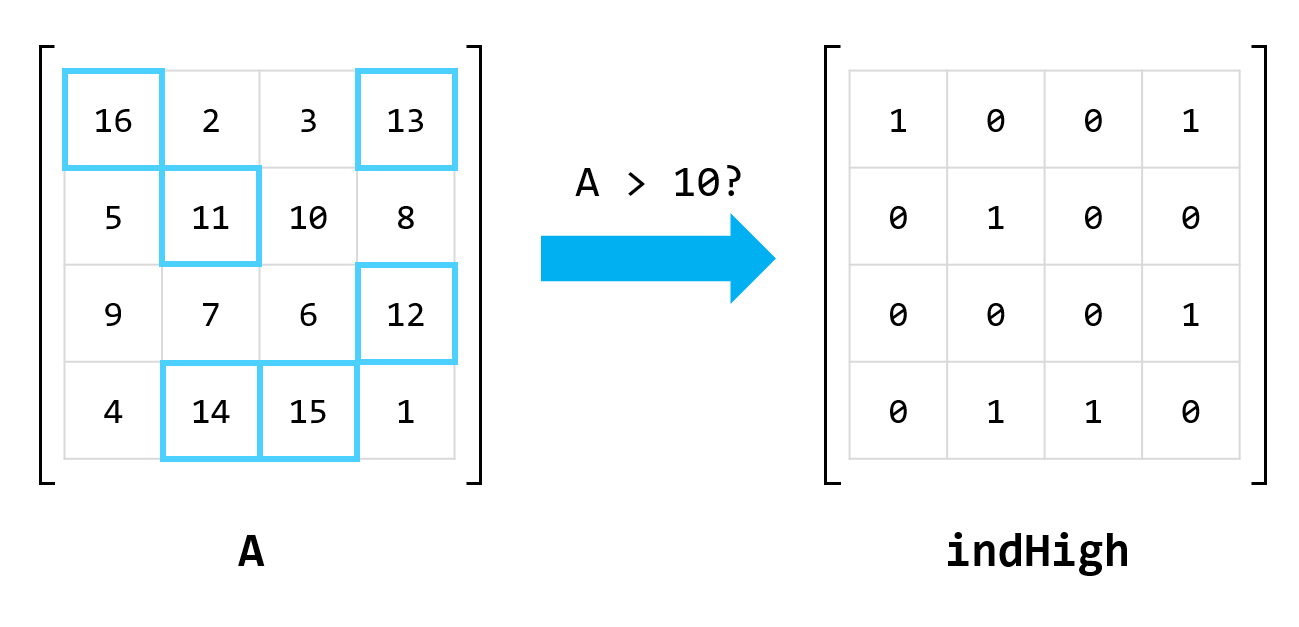

Logical variables have a value of 1 at the locations where the condition is true. When you use logical variables as indices, only the values at these true locations will be extracted or replaced.

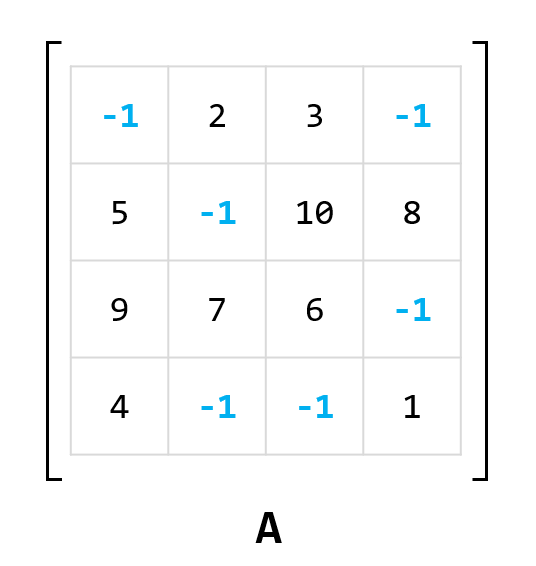

Try it yourself with another set of rainfall values:

rain4 = [6 8 99 99 9; 7 8 6 99 99; 9 7 7 99 8; 99 99 8 7 8]

This time, there are some strange values in the matrix. When the rainfall exceeds the maximum measurement of 10 inches, the sensor defaults to the value `99`. Our visualizations and analysis would be very wrong if we keep this default sensor value. So, change every `99` to `10`.

First, make a new logical matrix, `index99`, that locates all values equal to 99. Use the double-equals operator (`==)` to define the condition.

Now, use `index99` to select which elements in `rain4` to change, and change these elements to `10`.

Finally, use the function `pcolor` to visualize this matrix. Use the `colorbar` command to see what values the different colors on the figure represent.

## Calculations with Matrices

To perform a unit conversion on a matrix or to use multiple matrices in a calculation, you'll need to know how to do calculations with matrices.

### Elementwise Operations

When performing math operations between a single number (a scalar) and a matrix, the operation is applied to every element in the matrix.

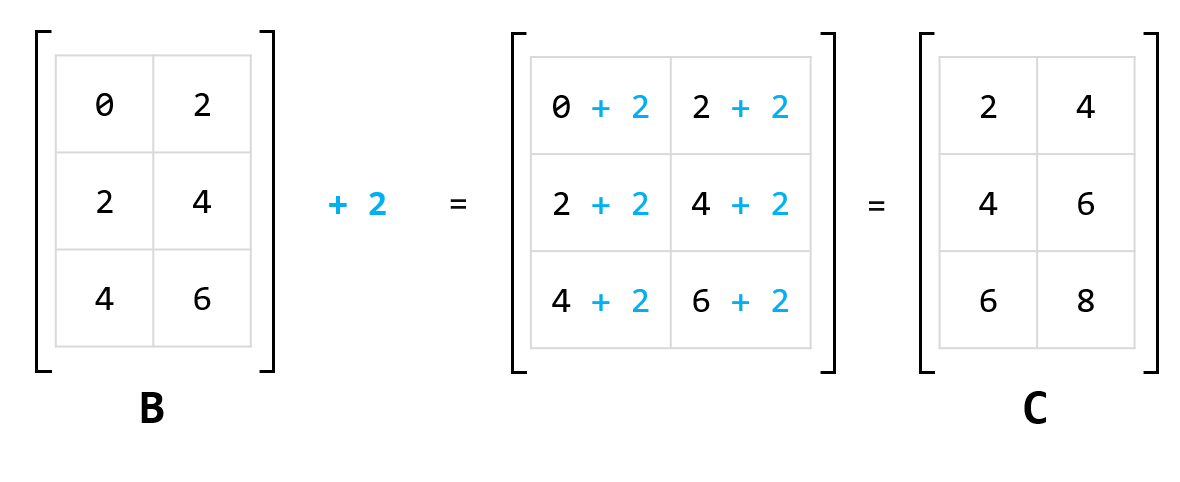

To add or subtract two *matrices*, they need to be the same size. The specified operation (addition or subtraction) is applied to the corresponding elements of each matrix.

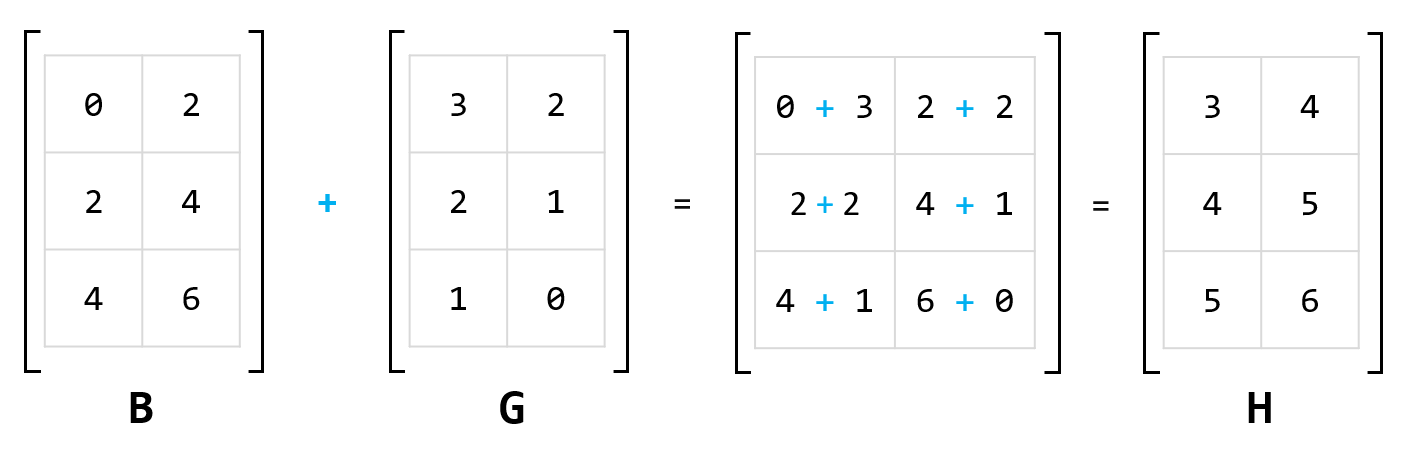

To multiply two matrices element by element, naturally, they need to have the same size. Add a dot before the operator for elementwise operations such as multiplication (.*), division (./) and exponentiation (.^). The `.^` operator is necessary for operations with scalars like `B.^2` because it's the same operation as `B.*B`. You'll see in the next section that operations without the dot (such as `B*B` or `B^2`) are entirely different operations.

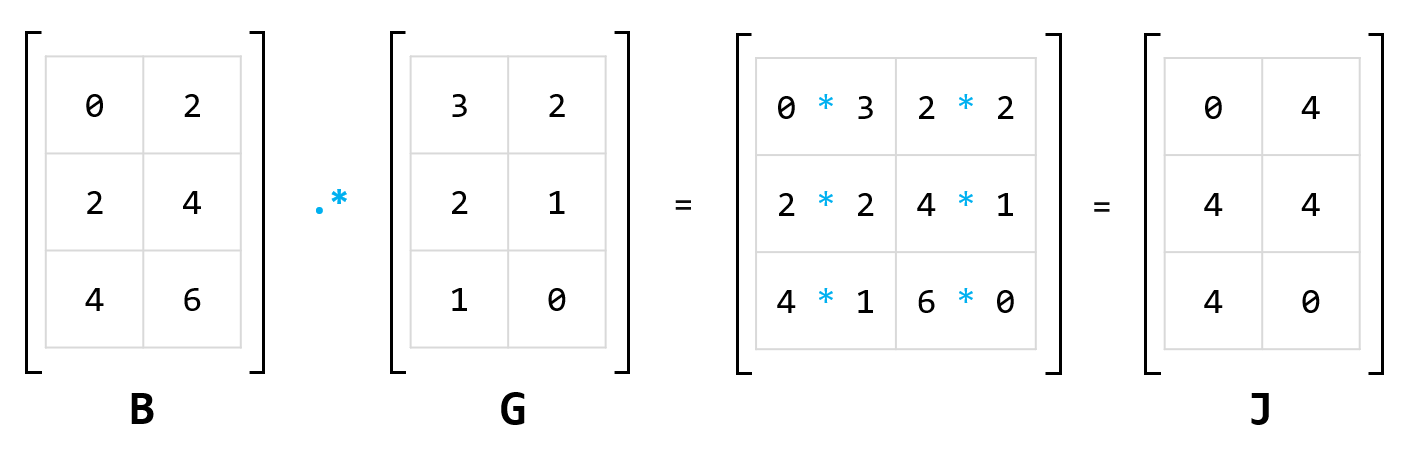

Try a scalar multiplication. Convert the values in `rain4` from inches to centimeters. To accomplish this, multiply `rain4` by `2.54`. Store the result in a new variable, `rain4cm`.

To check your work, make sure that the lower-right-hand element in `rain4cm` is `20.320`.

### Matrix Operations

Mathemetical operations between matrices have specific definitions. In the case of addition and subtraction, these operations work element by element, which you saw above. This is not true for multiplication, division and exponentiation.

Matrix multiplication, for example, requires that the inner dimensions of the matrices are the same. This means, a 3x2 matrix and a 2x4 matrix could be multiplied, because the inner dimension (2) matches. But you'll get an error if you try multiplying a 3x2 matrix and a 3x4 matrix.

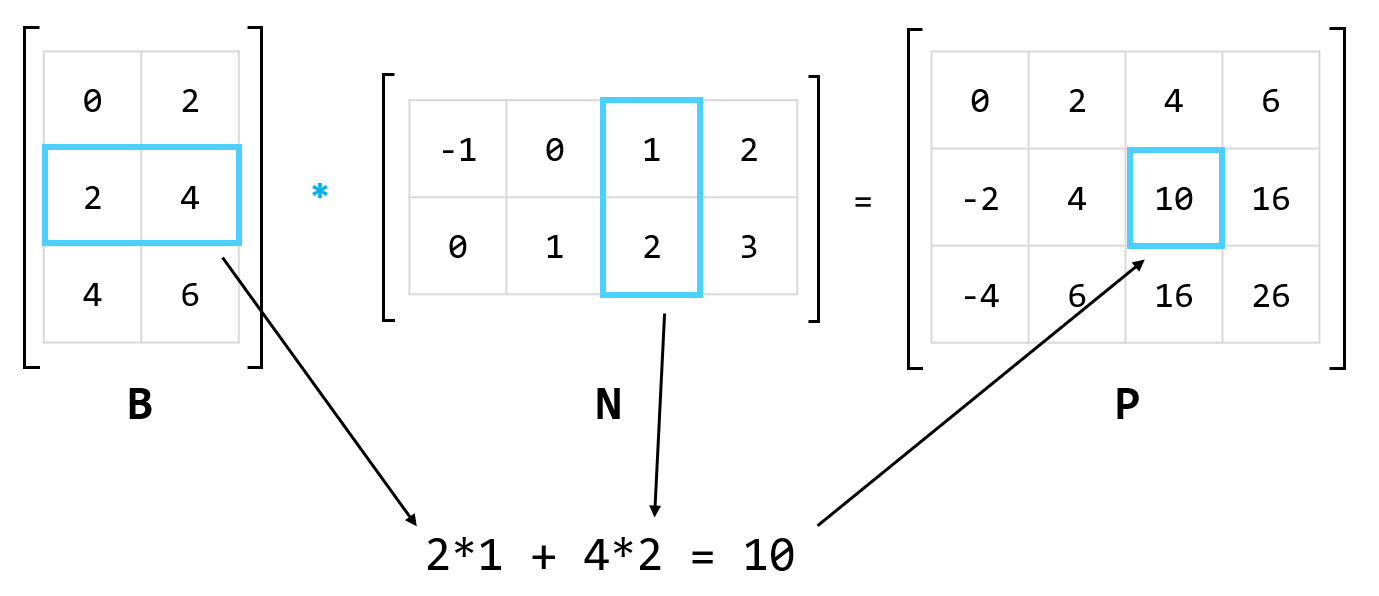

Try out elementwise multiplication and matrix multiplication with these 3x3 matrices:

Q = [1 2 4; 2 3 5; 3 4 6]
R = [1 2 1; 1 3 1; 1 4 1]

First, use elementwise multiplication (`.*`) to multiply the elements in `Q` by those in `R`.

Now use matrix multiplication (`*`) to multiply the matrix `Q` by the matrix `R`.

Finally, swap the order of the matrix multiplication performed above. Use matrix multiplication to multiply the matrix `R` by the matrix `Q`.

Go back and compare the results of these three operations. Notice that changing the order of a matrix multiplication affects the result. Pick out a few values in each of the three results above and figure out where those values came from.

### Transpose

If you need to switch the rows and columns of a matrix, you can do so with the transpose operator, `'`. Transposing a matrix will sometimes make your data much easier to work with. For example, you may want to use a function that performs some operation on the columns of a matrix, but your data is organized by row.

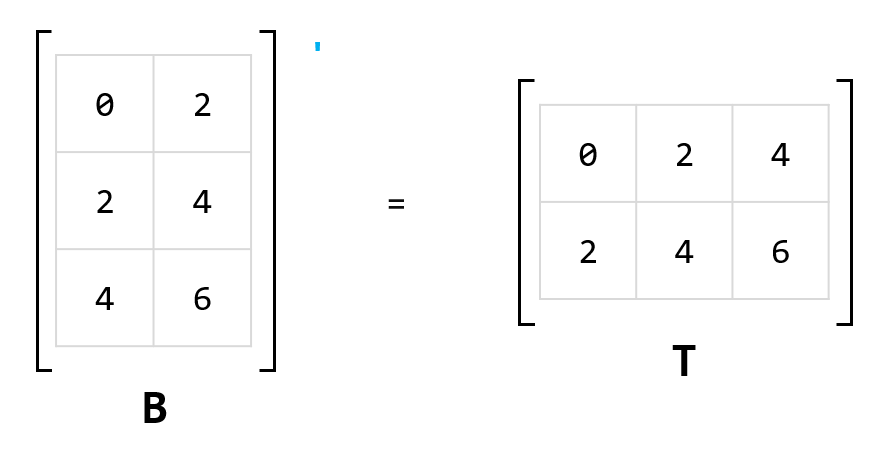

Transposed matrices have some interesting properties. For example, the following holds for any two matrices, `U` and `V`:

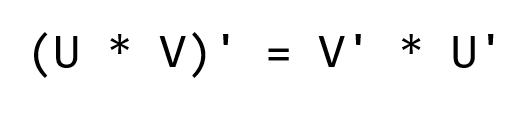

Demonstrate that this property holds between the following two matrices (each of which are populated with random integers between 1 and 20).

U = randi([1 20], 3, 2)
V = randi([1 20], 2, 2)

First, calculate the left-hand side of the equation, `(U * V)`'.

Next, calculate the right-hand side of the equation, `V' * U'`.

Finally, verify that the results of these two operations are equivalent. Rerun this section to try it again with different (randomly generated) values.

### Summary of 'Calculations with Matrices'

In this section, you learned about elementwise operations, matrix operations, and the transpose operator.

It can be difficult to keep track of the differences between elementwise and matrix operations. Some operations, like multiplication, have an elementwise operator (`A .* B`) because the standard operation (`A * B`) is already well-defined for two matrices. 

On the other hand, the addition operation does not have an elementwise version (there's no `A .+ B`) because the matrix operation `A + B` is already defined to work element by element. To help you keep track of the overlap between operations, refer to the venn diagram below.

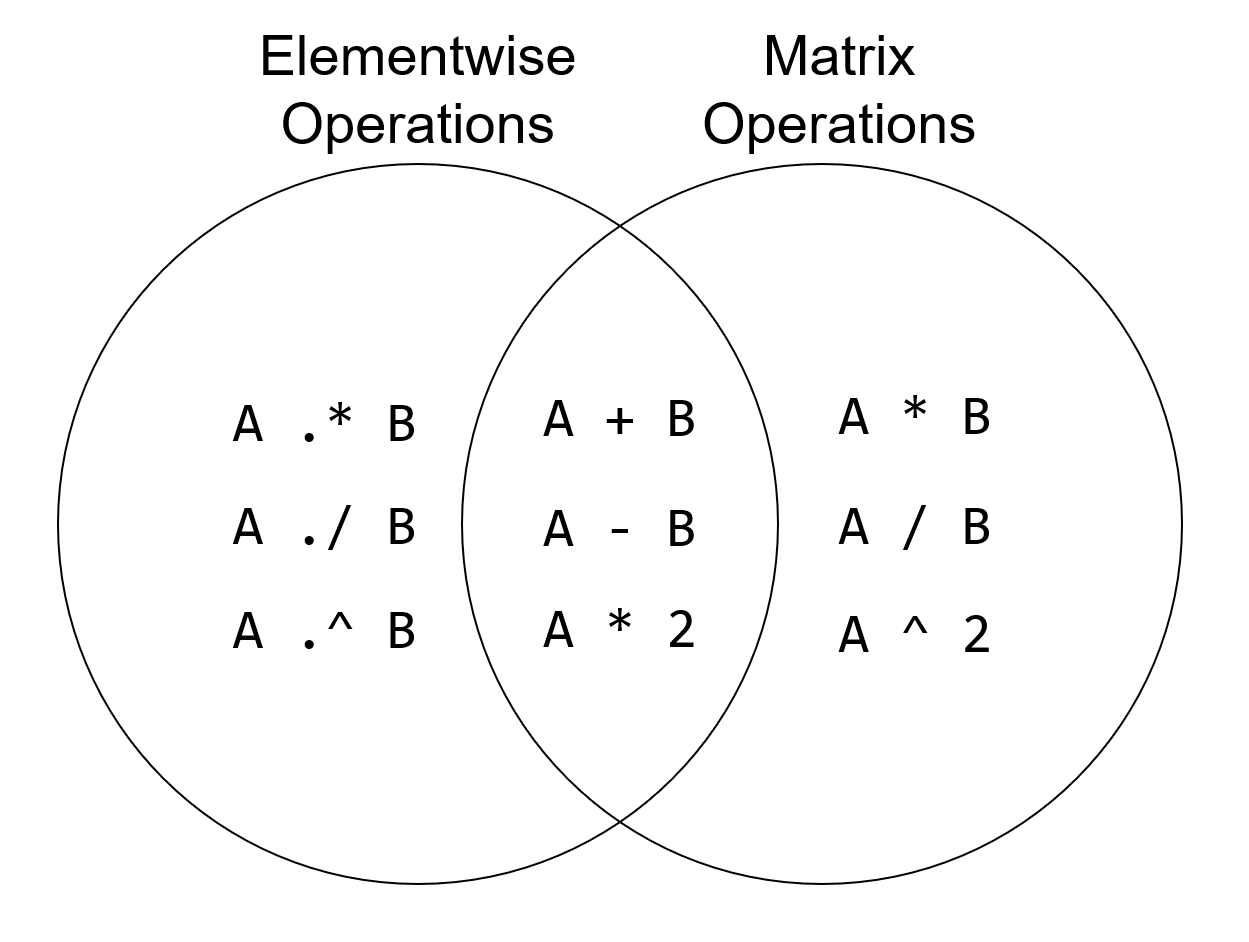

For more information about and examples of both elementwise operations and matrix operations, check out [this documentation page](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html).

Congratulations! You've worked through an essential topic of this course. Did you know that the name "MATLAB" stands for "**Mat**rix **Lab**oratory"? In the upcoming activity, you can check if you understand the important concepts of creating and working with matrices. Soon, you'll learn even more about working with matrices, including how to calculate statistics and apply trigonometric functions (sine, cosine, etc.).

*Copyright 2021 The MathWorks, Inc.*